# Lagrange Polynomials

Consider a grid $$\bar{t}=[t_0, \ldots , t_N]$$. A Lagrange polynomial is given by


$$$$x_N(t) = \sum_{i=0}^N \bar{x}_{i,N} \ell_{i,N}(t) , \qquad \ell_{i,N}(t) = \prod_{{k=0 , \quad k \neq i}}^{N} \frac{t-t_k}{t_i-t_k} . $$ $$


Notice that 


$$\ell_{i,N}(t_j) = \delta_{ij} =
\begin{cases} 
1 \qquad & i = j \\
0 & i \neq j ,
\end{cases} $$


where $$\delta_{ij}$$ is known as the Kronecker delta. The above property implies 


$$$x_{N}(t_j) = \bar{x}_{j,N} \, .$$$


In other words, the Lagrange polynomial evaluated at the $i$th time node is equal to the $i$th polynomial coefficient. The following figure provides examples of Lagrange polynomials and their coefficients:

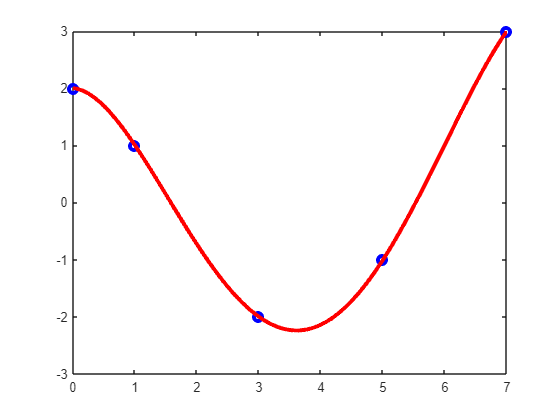

clear all
close all

time = 0:0.01:7;

t_nodes = [0 1 3 5 7];
xbar = [2 1 -2 -1 3];

xN = LagrangePoly(xbar,t_nodes,time);

figure
plot(t_nodes,xbar,'o','Linewidth',3,'Color','b'); hold on
plot(time,xN,'Linewidth',3,'Color','r');

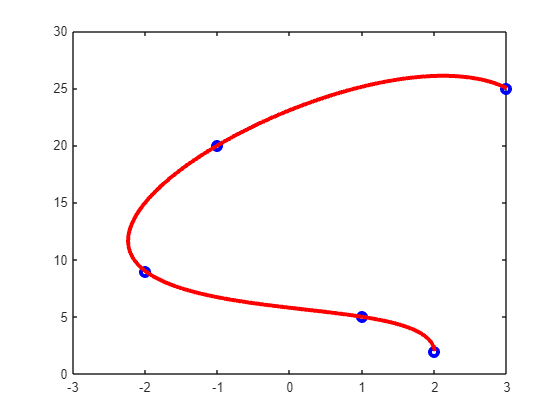

pbar = [2 1 -2 -1 3; ...
    2 5 9 20 25];

pNx = LagrangePoly(pbar(1,:),t_nodes,time);
pNy = LagrangePoly(pbar(2,:),t_nodes,time);
figure
plot(pbar(1,:),pbar(2,:),'o','Linewidth',3,'Color','b'); hold on
plot(pNx,pNy,'Linewidth',3,'Color','r');

# LGL Nodes

Legendre polynomials on the interval $$z \in [-1,1]$$are defined by the recurrence formula


$$$$L_0 (z) = 1 , \qquad L_1(z) = z , \qquad L_{i+1} (z) = \frac{2i+1}{i+1}zL_i(z) - \frac{i}{i+1}L_{i-1}(z), \qquad i \geq 1.$$ $$


Let $$L_N (z)$$ be the Nth order Legendre polynomial. The LGL nodes are $$z_0, z_1 , \ldots , z_N$$ where 


$$$$z_0 = -1 , \qquad z_N = 1 , $$$$


and $$z_1 , \ldots , z_{N-1}$$ are the zeros of $$L_N^\prime(z)$$.

The LGL nodes are defined over the interval $$z\in [-1,1]$$. To shift to the general interval $$t \in [0,t_f]$$, the following transformation is applied $$t_i = \frac{z_i + 1}{2}t_f$, $\forall i = 0,1,\ldots,N$.$

With a slight abuse of notation, in the remainder of this document the shifted Legendre polynomial on $$[0,t_f]$$ is defined as 


$$$$L_0 (t) = 1 , \qquad L_1(t) = \frac{2t-t_f}{t_f} , \qquad L_{i+1} (t) = \frac{2i+1}{i+1}\frac{2t-t_f}{t_f}L_i(t) - \frac{i}{i+1}L_{i-1}(t), \qquad i \geq 1.$$ $$


The following figures, obtained using the BeBOT Matlab toolbox, compare LGL nodes to equidistant nodes.

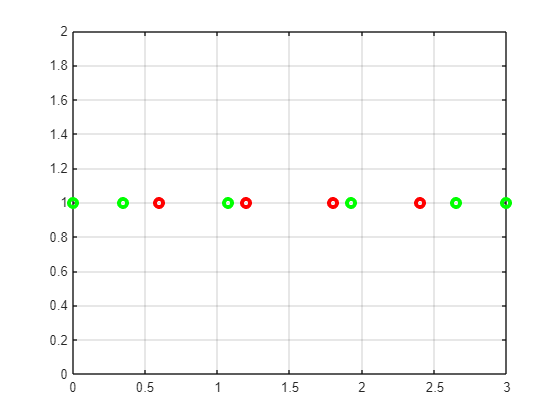

N = 5; % order
tf = 3;

%% Compute Equidistant nodes from 0 to tf
t_equi = linspace(0,tf,N+1);

figure
plot(t_equi,1,'o','Linewidth',3,'Color','r'); hold on
grid on

%% Compute LGL nodes from 0 to tf
[t_LGL,w,D] = LGL_PS(N,tf);
plot(t_LGL,1,'o','Linewidth',3,'Color','g'); 

# Orthogonal collocation

Given any function $$f(t)$
$, the polynomial $ $f_N(t)$
$ of degree N which passes through N+1 specified points of a function $$f(t)$$ is called the Lagrange interpolating polynomial. For points $$t_0, t_1, \ldots , t_N$$ and function values $f(t_0), f(t_1), \ldots , f(t_N)$this an be written as


$$\[
f_N(t) = \sum_{i=0}^N f(t_i) \ell_i(t).
\]$$


Note that the above equation implies $$$f_N(t_i) = f(t_i) . $$
$ For an arbitrary grid of time nodes $$t_0, t_1, \ldots , t_N$$, the Lagrange interpolating polynomial does not necessarily have pleasant convergence properties as $$N \rightarrow \infty$$. In fact, for an equi-spaced grid of nodes it has rather poor properties and examples functions can be found in which the maximum error actually increases with N (the Runge phenomenon). However, many schemes of non-equi-spaced nodes have been shown to mitigate the Runge phenomenon.  In fact, the Lagrange interpolating polynomial does have pleasant convergence properties when the grid $$t_0, t_1, \ldots , t_N$$ is given by the roots of orthogonal polynomials, e.g., the LGL nodes. We will now tackle an example.

## Example

Define the following functions


$$u_1(t) = \frac{1}{\sqrt{1+(T-t)^2}}$$



$$u_2(t)=\frac{T-t}{\sqrt{1+(T-t)^2}}$$


with $T=12.$

T = 12;
u1 = @(t) 1./(sqrt(1+(T-t).^2));
u2 = @(t) (T-t)./(sqrt(1+(T-t).^2));
t = 0:0.01:T;
u1fig = figure();
plot(t,u1(t),'LineWidth',3,'Color','k'); hold on
grid on
u2fig = figure();
plot(t,u2(t),'Linewidth',3,'Color','k'); hold on
grid on

We approximate the functions using the Lagrange polynomial interpolating at equidistant nodes with order N = 5

N = 5;
t_nodes = linspace(0,12,N+1);
u1_nodes = u1(t_nodes);
u2_nodes = u2(t_nodes);

figure(u1fig)
plot(t_nodes,u1_nodes,'o','Color','r','LineWidth',3);
figure(u2fig)
plot(t_nodes,u2_nodes,'o','Color','r','LineWidth',3);

u1_N = LagrangePoly(u1_nodes,t_nodes,t);
u2_N = LagrangePoly(u2_nodes,t_nodes,t);

figure(u1fig)
plot(t,u1_N,'Color','r','LineWidth',3);
figure(u2fig)
plot(t,u2_N,'Color','r','LineWidth',3);

Now, we approximate the functions using the Lagrange polynomial interpolating at equidistant nodes with order N = 70 (which diverges)

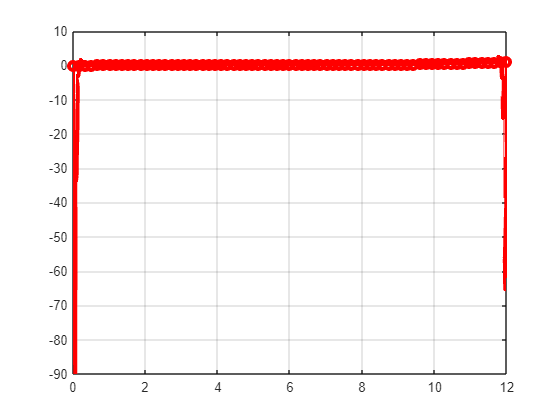

N = 70;
t_nodes = linspace(0,12,N+1);
u1_nodes = u1(t_nodes);
u2_nodes = u2(t_nodes);

figure(u1fig)
plot(t_nodes,u1_nodes,'o','Color','r','LineWidth',3);
figure(u2fig)
plot(t_nodes,u2_nodes,'o','Color','r','LineWidth',3);

u1_N = LagrangePoly(u1_nodes,t_nodes,t);
u2_N = LagrangePoly(u2_nodes,t_nodes,t);

figure(u1fig)
plot(t,u1_N,'Color','r','LineWidth',3);

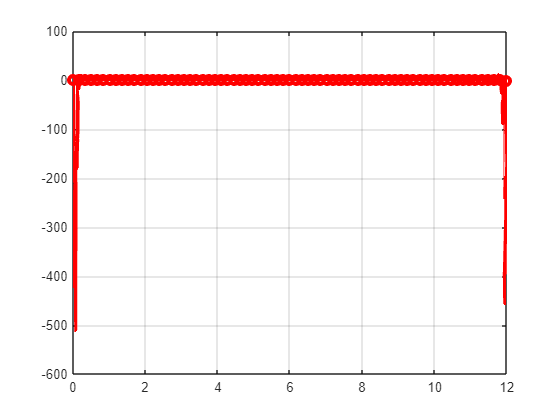

figure(u2fig)
plot(t,u2_N,'Color','r','LineWidth',3);

Finally, we approximate the functions using the Lagrange polynomial interpolating at LGL nodes:

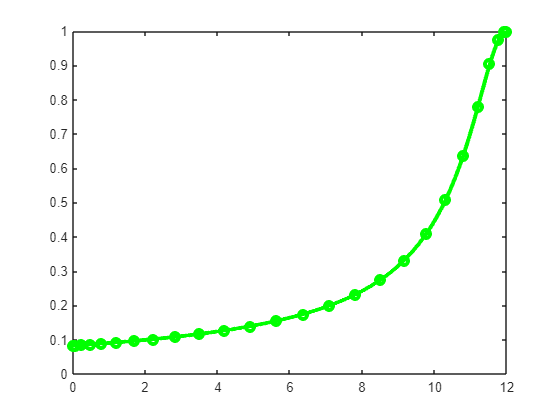

%% Approximation at LGL nodes
N = 25;
[t_nodes,w,Dm] = LGL_PS(N,T);
u1_nodes = u1(t_nodes);
u2_nodes = u2(t_nodes);
u1_N = LagrangePoly(u1_nodes,t_nodes,t);
u2_N = LagrangePoly(u2_nodes,t_nodes,t);

figure
plot(t_nodes,u1_nodes,'o','Color','g','LineWidth',3); hold on
plot(t,u1_N,'Color','g','LineWidth',3);

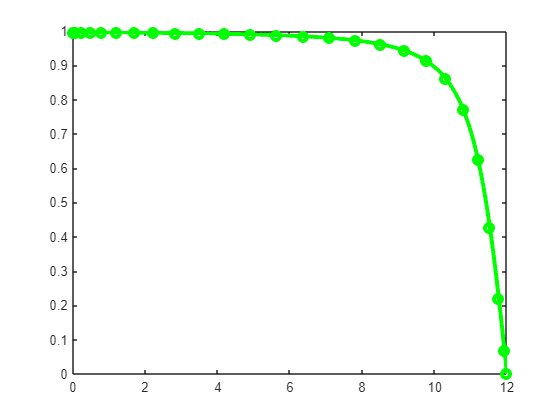


figure
plot(t_nodes,u2_nodes,'o','Color','g','LineWidth',3); hold on
plot(t,u2_N,'Color','g','LineWidth',3);

# Differentiation

The approximation of a function $$f(t)$




$ by the N-th order Lagrange polynomial $$f_N(t)$$ also provides an estimate for the derivative $$\dot{f}(t)$$ through the derivative $$\dot{f}_N(t)$$:


$$$$
\dot{f}(t) \approx \dot{f}_N(t) = \sum_{i=0}^N f(t_i)\dot{\ell}_i(t)
$$$$


At the node $t_0, t_1 , \ldots , t_N$ this creates the system of equations:


$$$$
\dot{f}_N(t_k) = \sum_{i=0}^N f(t_i)\dot{\ell}_i(t_k), \qquad k=0,\dots,N
$$ $$


which can be expressed in matrix form as:


$$
\left[\matrix{
\dot{f}_N(t_0) \cr
\dot{f}_N(t_1)  \cr
\vdots \cr
\dot{f}_N(t_N)}\right] = 

=
[{f}(t_0) , {f}(t_1) , \ldots , f(t_N)]
\underbrace{\left[\matrix{
	\dot{\ell}_0(t_0) & \dot{\ell}_0(t_1) & \cdots & \dot{\ell}_0(t_N)  \cr
	\dot{\ell}_1(t_0) & \dot{\ell}_1(t_1) & \cdots & \dot{\ell}_1(t_N) \cr
	\vdots & \vdots & \ddots & \vdots \cr
	\dot{\ell}_N(t_0)  & \dot{\ell}_N(t_1)  & \cdots & \dot{\ell}_N(t_N)}\right]}_{\rightarrow\text{Differentiation Matrix: D}}
$$$$


The quantities $$\dot{\ell}_i(t_k)$ $are constants which are independent of the function values and are determined entirely by the choice of nodes. The $$(N+1)\times(N+1)$$matrix is an example of a differentiation matrix. The choice of nodes and basis functions determines the matrix. When $t_0, t_1, \ldots , t_N$ are the LGL nodes, the matrix


$$$$
D = 
\left[\matrix{
\dot{\ell}_0(t_0) & \dot{\ell}_0(t_1) & \cdots & \dot{\ell}_0(t_N)  \cr
\dot{\ell}_1(t_0) & \dot{\ell}_1(t_1) & \cdots & \dot{\ell}_1(t_N) \cr
\vdots & \vdots & \ddots & \vdots \cr
\dot{\ell}_N(t_0)  & \dot{\ell}_N(t_1)  & \cdots & \dot{\ell}_N(t_N) \cr
}\right]
$$$$


is called the LGL Differentiation matrix. Component-wise its values can be computed to be:


$$\[
D_{ik} = \ell_{i}(t_k) = 
\begin{cases}
\frac{L_N(t_k)}{L_N(t_i)}\frac{1}{t_k-t_i} &\mbox{if } k\neq i \\
\frac{-N(N+1)}{2t_f} &\mbox{if }k=i=0 \\
\frac{N(N+1)}{2t_f} &\mbox{if }k=i=N \\
0 & \mbox{else}
\end{cases} 
\]$$


where $$L_N(z)$$ is the shifted N-degree Legendre polynomial.

## Example

Consider the functions $u_1(t)$and $u_2(t)$defined earlier. Their derivatives are 


$$\dot{u}_1(t)=\frac{T-t}{((T-t)^2+1)^{3/2}}$$



$$\dot{u}_2(t) = -\frac{1}{(T^2-2Tt+t^2+1)^{3/2}}$$


These are defined and plotted as follows:

u1dot = @(t) (T-t)./((T-t).^2+1).^(3/2);
u2dot = @(t) -1./(T^2-2*T*t+t.^2+1).^(3/2);
% Plot the derivatives in [0,T]
fu1dot = figure;
plot(t,u1dot(t),'Linewidth',3,'Color','k'); hold on
grid on
fu2dot = figure;
plot(t,u2dot(t),'Linewidth',3,'Color','k'); hold on
grid on

These derivatives are then approximated by Lagrange polynomials as follows:

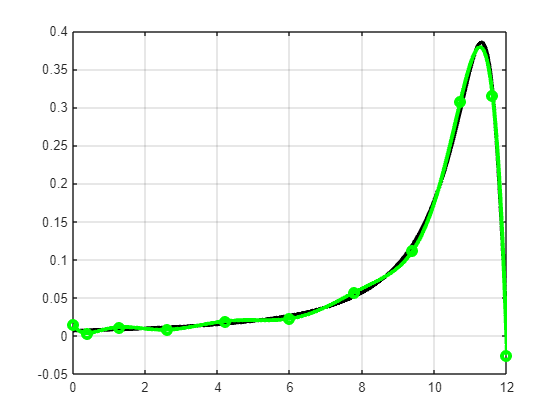

N = 10;
[t_nodes,w,Dm] = LGL_PS(N,T);
u1_nodes = u1(t_nodes);
u2_nodes = u2(t_nodes);

%% Approximate the derivative
u1dot_nodes = u1_nodes*Dm;
u2dot_nodes = u2_nodes*Dm;

figure(fu1dot)
plot(t_nodes,u1dot_nodes,'o','Color','g','LineWidth',3);

figure(fu2dot)
plot(t_nodes,u2dot_nodes,'o','Color','g','LineWidth',3);

u1dot_N = LagrangePoly(u1dot_nodes,t_nodes,t);
u2dot_N = LagrangePoly(u2dot_nodes,t_nodes,t);

figure(fu1dot)
plot(t,u1dot_N,'Color','g','LineWidth',3);

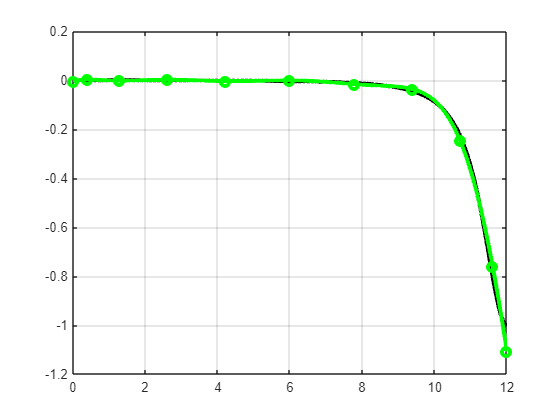

figure(fu2dot)
plot(t,u2dot_N,'Color','g','LineWidth',3);

# LGL Quadrature

Numerical quadrature is an approximation method for definite integrals. LGL quadrature establishes weights $$w_i$$ for given LGL nodes $$t_i$$ to approximate an integral as a finite sum.


$$\[
\int_a^b  f(t) dt \approx \sum_{i=1}^N w_i f(t_i)
\]$$


Note that the above finite sum involves evaluation of the function $$f(t)$$ at the LGL nodes $t_0, t_1 , \ldots , t_N$. In order to determine the weights $$w_i$$, tools from numerical and variational analysis can be used. For LGL quadrature, the weights are computed as follows: 


$$w_0 = w_N =  \frac{t_f}{N(N+1)}, \qquad w_i = \frac{t_f}{N(N+1){\left[ L_{N}(t_i) \right]}^2},    \qquad i = 1, \dots, N-1$$


Here we perform numerical integration of $u_1(t)$and $u_2(t)$. The deifnite integrals can be computed analytically as


$$\int_0^T u_1(t)dt = \text{asinh}(T) , \quad \int_0^T u_2(t)dt = \sqrt{T^2+1}-1$$


intu1 = asinh(T);
intu2 = sqrt(T^2+1)-1;
%% Numerical Integration
% Compute weights
N = 100;
[tnodes, w, D] = LGL_PS(N,T);
% Evaluate function at the nodes
u1_N = u1(tnodes);
u2_N = u2(tnodes);
% Compute integrals
int_u1 = u1_N*w;
int_u2 = u2_N*w;
% Compute error
err1 = int_u1 - intu1

err1 = 1.7764e-15

err2 = int_u2 - intu2

err2 = 3.5527e-15